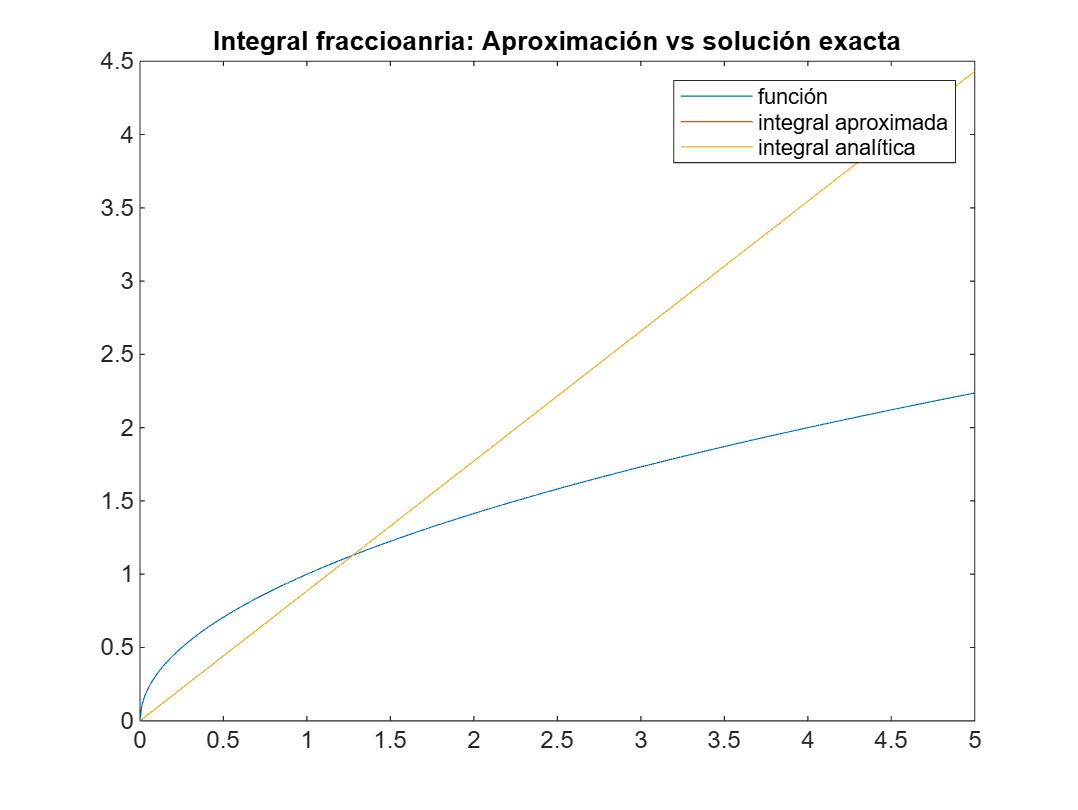

% vector de tiempo
t = 0:0.01:5; 
% coeficientes de convolucion
kernel = gen_coeffs(-0.5,0.5,t);
% función a integrar 
f = t.^0.5;
% convolución para obtener la solución
df = conv(f,kernel);
% graficar función, derivada aproximada y analítica 
sl = gamma(1.5).*t;
plot(t,f,t,df(1:length(t))',t,sl)
legend('función','integral aproximada','integral analítica')
title('Integral fraccioanria: Aproximación vs solución exacta')



function coeffs = gen_coeffs(alpha, beta, t)
T = t(2) - t(1); 
L = length(t); 

k = (1:L-1)';
E = cumprod([(T*beta)^(-alpha); 1 - (1+alpha)./k]);
r = (1-beta)/beta;
Psi = cumprod([1; (1-alpha)./k - 1].*[1;repmat(r,L-1,1)]);
coeffs = conv(E, Psi);
coeffs= coeffs(1:L+1);
end